# PODSTAWY PROGRAMOWANIA W JĘZYKU MATLAB

## Funkcje i zagadnienia przydatne w trakcie realizacji przedmiotu WNUM

Opracował: K. Król

**---------------------------------------------------------------------------------------------------------------------------------------------**

**UWAGA! Zaleca się pracować z niniejszym skryptem ustawiając opcję "View" -> "Output on Right"**

**---------------------------------------------------------------------------------------------------------------------------------------------**

### Randomizacja

W ramach laboratoriów z WNUM będziemy czasem starali się zasymulować zaburzenie jakichś danych wejściowych na zadanym poziomie w sposób losowy. Takie podejście pozwoli nam badać wpływ wyboru metody na dokładność wyniku lub czułość metody na błędy mogące pojawić się w danych wejściowych.

Skąd mogą pojawić się błędy w danych wejściowych?

- Oczywistym źródłem błędów w danych wejściowych jest szum pomiarowy, kiedy dane pochodzą z jakichś pomiarów,

- Jeżeli jednak dane nie pochodzą z pomiarów to przez sam fakt, że zostały zapisane w formie cyfrowej, obarczone są błędem na jakimś poziomie - maksymalny błąd względny wynosi ***eps***. Wtedy zaburzenie danych pomiarowych symuluje nam co by się stało gdybysmy do obliczeń przyjęli typ danych o mniejszej precyzji.

W celu oceny właściwości numerycznych związanych z błędem, którym są obarczone dane wejściowe, będziemy porównywać działanie metod numerycznych na danych testowych (dokładnych) oraz zaburzonych. Do ich otrzymania możemy użyć funkcji ***rand()*** i ***randn()***. Pierwsza z nich służy do generacji liczb losowych z rozkładem równomiernym, druga z rozkładem normalnym. Obie jednak generują liczby losowe z zakresu <0,1>. Są to wiec tylko liczby dodatnie. Tymczasem błąd numeryczny powinien mieć wartość zarówno dodatnią jak i ujemną i niekoniecznie o wartości maksymalnej równej 1. Dlatego aby wygenerować zaburzenie losowe w sensie numerycznym, należy ten przedział przekształcić.

Zasadniczo można to zrobić na dwa sposoby: addytywny i multiplikatywny. Jeden opiera się na dodaniu do oryginalnego wektora zaburzeń, a drugi na pomnożeniu wartości oryginalnej (oryginalnego wektora) przez wektor zaburzeń. Różnica może wydawać się nieistotna, ale jak Państwo powinni wiedzieć, w świecie metod numerycznych istnieje bardzo duża różnica pomiędzy propagacją błędu w operacji dodawania i mnożenia. W niektórych zagadnieniach może odgrywać to znaczącą rolę.

% Multiplikatywny sposób generowania wektora zburzonego
% parametry zaburzenia: równomierne, na poziomie 5% wartości bazowej
% wektora A

A = [  2 3 4 5 6 7 8 9 10]; % Nasz dokładny wektor
t = 0.05;                   % Poziom zaburzenia

A_zab = A.*( 1+t.*2*(rand(size(A))-0.5))  % 2*(rand(size(A))-0.5) to wektor o tej samej długości co A, składający się z losowych liczb przedziału <-1;1>

%Sprawdźmy czy rzeczywiście jest max 5%
A_zab./A-1

A_zab =     1.9784    3.0466    3.8685    5.1030    5.7191    6.8438    7.6369    8.6374   10.3235


ans =    -0.0108    0.0155   -0.0329    0.0206   -0.0468   -0.0223   -0.0454   -0.0403    0.0323


% Addytywny sposób generowania wektora zburzonego
% parametry zaburzenia: równomierne, na poziomie 5% wartości bazowej
% wektora A

A = [  2 3 4 5 6 7 8 9 10]; % Nasz dokładny wektor
t = 0.05;                   % Poziom zaburzenia

A_zab = A+A.*t.*2*(rand(size(A))-0.5)    % 2*(rand(size(A))-0.5) to wektor o tej samej długości co A, składający się z losowych liczb przedziału <-1;1>

A_zab =     2.0992    2.8735    3.9771    4.8033    6.2771    6.6532    8.2199    9.2856   10.3687



%Sprawdźmy czy rzeczywiście jest max 5%
A_zab./A-1

ans =     0.0496   -0.0422   -0.0057   -0.0393    0.0462   -0.0495    0.0275    0.0317    0.0369


## Korzystanie z dokumentacji

W trakcie trwania laboratoriów prawdopodobnie nie raz trzeba będzie skorzystać z dokumentacji. Większość funkcji i mechanizmów opisanych w tym tutorialu mają różnorakie przeciążenia i opcje wykorzystania, z których czasem trzeba będzie skorzystać. Dlatego należy umieć posługiwać się pomocą MATLAB'a.

Podstawową komendą do wywoływania dokumentacji jest komenda ***doc***:

**doc <nazwa_komendy>**

Spowoduje ona wyświetlenie dokumentacji na dany temat w formie dokumentu html. Jeżeli z jakichś względów zależy nam na szybkości, albo dokumentacji w formie tekstowej przydatna jest komenda:

**help <nazwa_komendy>**

która wyświetli pomoc w postaci tekstu na konsoli.

## Przydatne funkcje MATLAB

Poniżej zamieszczamy spis przydatnych w trakcie realizacji zajęć z WNUM ogólnych funkcji MATLAB, o istnieniu których warto wiedzieć:

- ***min(), max(), mean()*** - funkcje zwracające wartość największą, najmniejszą albo średnią. W przypadku funkcji min i max mogą też zwracać indeksy położenia wartości największej/najmniejszej.

- ***linspace(), logspace()*** - funkcje generujące wektory z konkretnym rozkładem punktów

- ***zeros(), ones(), eye()*** - funkcje do generacji macierzy zer/jedynek albo macierzy jednostkowych o dowolnym rozmiarze

- ***sum()*** - sumuje wektor. Cały bądź po kolumnach/wierszach

- ***size(), length(), numel()*** - funkcje zwracające wymiary elementów. Dokładny opis w module 2.

- ***norm()*** - funkcja licząca normę z wektora (dowolną). Domyślnie liczy normę drugą.

- **exp(), log(), log10(), sin(), cos(), tan(), cot(), asin(), acos(), atan(), acot()**  - funkcje matematyczne liczące odpowiednio: eksponens, logarytm naturalny, logarytm o podstawie 10, funkcje trygonometryczne, funkcje odwrotne do funkcji trygonometrycznych

**UWAGA! Zwróć uwagę, że liczba Eulera '*****e'***** tj. podstawa logarytmu naturalnego, nie jest zdefiniowana jako stała w MATLAB (jak np. pi). Dlatego aby ją wyznaczyć trzeba wywołać funkcję e(1).**

## **Reprezentacja wielomianów w MATLAB**

Wielomiany są funkcjami z których często korzystamy w metodach numerycznych ze względu na łatwość wyznaczania pochodnych i całek z wielomianów. W MATLAB wielomiany mogą być reprezentowane w specjalny sposób w postaci wektora współczynników od największego do najmniejszego. Przykładowo wektor:

A = [1 2 3 0 5];

A_calka =     0.2000    0.5000    1.0000         0    5.0000         0


A_pochodna =      4     6     6     0


może zostać zinterpretowany jako wielomian:


$$A=x^4+2x^3+3x^2+5$$


Największa potęga wynosi 4 ponieważ wektor A ma 5 elementów (piąty jest czynnik x^0=1 czyli czynnik stały). Zwróć uwagę mimo, że w wielomianie nie występuje czynnik liniowy to musi on być zapisany w wektorze jako 0 żeby interpretacja wektora jako wielomianu się udała, czyli *de facto*:


$$A=x^4+2x^3+3x^2+0x+5$$


Taki zapis wielomianów jest bardzo wygodny w użytkowaniu. na takim zapisie wielomianów działają funkcje, których nazwy zaczynają się od ***poly...*** np.:

- ***polyint()*** - zwraca wektor współczynników wielomianu będącego całką z wielomianu wejściowego

- ***polyder()*** - zwraca wektor współczynników wielomianu będącego pochodną z wielomianu wejściowego

- ***polyval()*** - zwraca wartości wielomianu opisanego współczynnikami w wybranych punktach

- ***polyfit()*** - wykonuje interpolację bądź aproksymację wielomianową, zwracając wynik w postaci wektora współczynników wielomianu

% Przykładowo 

A = [1 2 3 0 5];

Wielomian: $A=x^4+2x^3+3x^2+5$

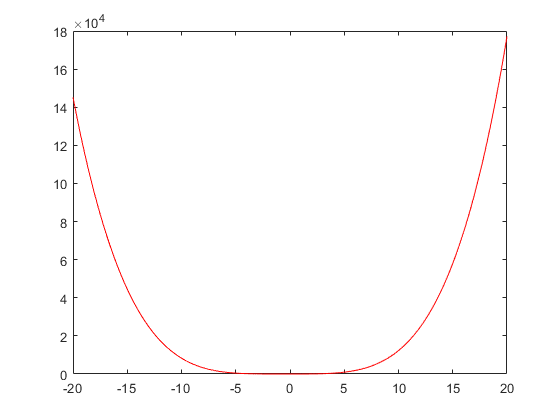

A_calka = polyint(A)

Czyli wielomian: $A_{calka}=\frac{1}{5}x^5+\frac{1}{2}x^4+1x^3+0x^2+5x+0$

A_pochodna = polyder(A)

Czyli wielomian: $A_{pochodna}=4x^3+6x^2+6x+0$

% Jeżeli byśmy chcieli wyrysować wielomian A to mozemy zrobić to tak:

x=[-20:0.01:20];

plot(x,polyval(A,x),'r');
 

## Ćwiczenia

Wykonaj podane dalej ćwiczenia żeby przekonać się jak idzie Ci programowanie w MATLAB i ile czasu musisz poświecić aby sprawnie się w nim poruszać. **Pamiętaj na laboratoriach masz ograniczoną ilość czasu na wykonanie zadań, nawet jeżeli wiesz, jak je rozwiązać!**

**Ćwiczenie 1 **- procent składany

Przypuśćmy, że dysponujesz kwotą 10 000 zł. Inwestujesz ją w inwestycję przynoszącą stałe oprocentowanie rzędu 2% w skali roku. Wykreśl kwotę z tej inwestycji w kolejnych okresach kapitalizacji (np. z kapitalizacją miesięczną, kwartalną, roczną) w perspektywie 20 lat. Depozyt rośnie zgodnie z procentem składanym wg funkcji:

$K=K_{0}{\left( 1+\frac{p}{100}\right)}^n$,

gdzie K0 to kapitał początkowy, p to oprocentowanie w skali okresu kapitalizacji, a n to numer okresu kapitalizacji. 

Następnie sprawdź jak przebieg wykresu i zysk zmienią się, gdy:

a) oprocentowanie będzie większe o 0.2%

b) kapitał początkowy wzrośnie o 10%

**Ćwiczenie 2** - wydajność obliczeń

Znany w starożytności algorytm wyznaczania pierwiastka kwadratowego tzw. wzór Herona mówi, że:

- jeżeli przyjmiemy $x_0 \approx \sqrt{S}$

- to wartość pierwiastka możemy obliczyć stosując następujący wzór iteracyjny:


$$x_{n+1} =\frac{1}{2}\left(x_n +\frac{S}{x_n }\right)$$


Zaimplementuj ten algorytm dla znanego rozwiązania x0=3 (pierwiastek z 9). Obliczenia zatrzymaj kiedy błąd bezwzględny rozwiązania będzie nie większy niż 1e-5. Wyrysuj na osobnym wykresie błąd rozwiązania w funkcji numeru iteracji.

Warszawa, 27.02.2021 r.                                                                                                           **© **K. Król

Sem. 21L